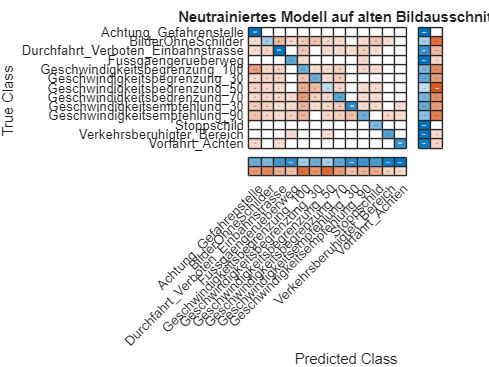

% Pfad zum Bildordner
imageFolder = 'C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\99_Trainingsdatensaetze\03_13Kat_Alle Schilder';
imdsSchilder = imageDatastore(imageFolder, "IncludeSubfolders", true, "LabelSource", "foldernames");
augTrain  = augmentedImageDatastore([48 48 3], imdsSchilder, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');

% Beispiel: Angenommen dein Netz heißt 'net'
load('meinNetz_weitertrainiert.mat'); % lädt das trainierte Netz
net = net; % falls nötig

% Bildgröße anpassen (abhängig vom Netz)
% inputSize = net.Layers(1).InputSize(1:2);

% Klassenlabels (falls vorhanden)
% classNames = {'KeinSchild', 'Schild'}; % Beispiel

%Schätzung Trainingsdatensatz
tbl = readall(augTrain);           % Liefert eine Tabelle mit Bildern
imgs = tbl{:,1};                 % Hole die Bilder aus der ersten Spalte als Cell-Array
TTrain = imdsSchilder.Labels;
classNames = categories(TTrain);

XTrain = cat(4,imgs{:});
XTrain = single(XTrain);

outputs  = minibatchpredict(net,XTrain);
YTrain = onehotdecode(squeeze(outputs)',classNames,2);
%% Confusion Matrix mit Precision und Recall
figure;

cm = confusionchart(TTrain, YTrain);

cm.Title = ...
    "Neutrainiertes Modell auf alten Bildausschnitten";

% In den Zellen weiterhin absolute Bildanzahlen anzeigen
cm.Normalization = "absolute";

% Rechts neben den Zeilen:
% korrekter Anteil entspricht dem Recall
cm.RowSummary = "row-normalized";

% Unter den Spalten:
% korrekter Anteil entspricht der Precision
cm.ColumnSummary = "column-normalized";

confMat = confusionmat(imdsSchilder.Labels, YTrain);

%% Precision, Recall und F1 je Klasse berechnen

[confMat, classOrder] = confusionmat(TTrain, YTrain);

truePositive = diag(confMat);

anzahlTatsaechlich = sum(confMat, 2);
anzahlVorhergesagt = sum(confMat, 1)';

recall = truePositive ./ anzahlTatsaechlich;
precision = truePositive ./ anzahlVorhergesagt;

% Division durch null abfangen
recall(~isfinite(recall)) = 0;
precision(~isfinite(precision)) = 0;

f1Score = 2 .* precision .* recall ./ ...
    (precision + recall);

f1Score(~isfinite(f1Score)) = 0;


%% Tabelle je Klasse erstellen

kennzahlen = table( ...
    string(classOrder(:)), ...
    anzahlTatsaechlich, ...
    anzahlVorhergesagt, ...
    truePositive, ...
    precision * 100, ...
    recall * 100, ...
    f1Score * 100, ...
    'VariableNames', { ...
        'Klasse', ...
        'TatsaechlicheBilder', ...
        'VorhergesagteBilder', ...
        'RichtigErkannt', ...
        'PrecisionProzent', ...
        'RecallProzent', ...
        'F1Prozent'});

disp(kennzahlen);

                   Klasse                   TatsaechlicheBilder    VorhergesagteBilder    RichtigErkannt    PrecisionProzent    RecallProzent    F1Prozent
    ____________________________________    ___________________    ___________________    ______________    ________________    _____________    _________

    "Achtung_Gefahrenstelle"                        377                    755                 377               49.934               100         66.608  
    "BilderOhneSchilder"                            408                    194                  75                38.66            18.382         24.917  
    "Durchfahrt_Verboten_Einbahnstrasse"            509                    556                 373               67.086            73.281    



%% Nach Excel schreiben

excelDatei = ...
    "Klassenkennzahlen_neutrainiertes_Modell_alte_Bilder.xlsx";

writetable(kennzahlen, excelDatei);

fprintf("Kennzahlen gespeichert unter:\n%s\n", ...
    fullfile(pwd, excelDatei));

Kennzahlen gespeichert unter:
C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\04_ModelleTrainieren\Klassenkennzahlen_neutrainiertes_Modell_alte_Bilder.xlsx



accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 55.46%


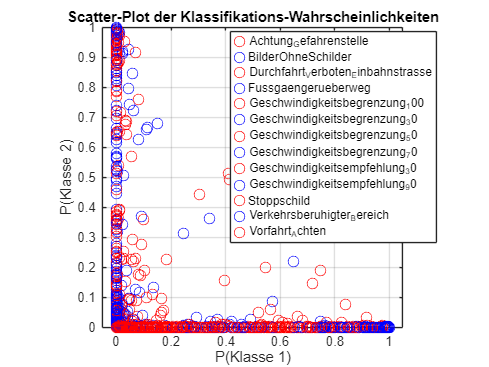


prob = squeeze(outputs); 

% % 4) Scatterplot erstellen (mit Farbcode nach true Label)
% figure;
% gscatter(...
%     prob(1,:), ...                    % X-Werte: P(Klasse 1)
%     prob(2,:), ...                    % Y-Werte: P(Klasse 2)
%     TTrain, ...                       % Gruppierung nach echtem Label
%     'rb', ...                         % Farben: rot/blau
%     'o', ...                          % Marker: Kreis
%     8);                               % Markergröße
% 
% xlabel('P(Klasse 1)');
% ylabel('P(Klasse 2)');
% title('Scatter-Plot der Klassifikations-Wahrscheinlichkeiten');
% legend(categories(TTrain), 'Location', 'best');
% grid on;
% axis square;



%Falsch erkantte Bilder anzeigen
trueLabelsTrain = imdsSchilder.Labels;

wrongIdxtrain = find(YTrain ~= trueLabelsTrain);


% 
% for i = 1:length(wrongIdxtrain)
%     img = readimage(imdsSchilder, wrongIdxtrain(i));
%     figure;
%     imshow(img);
%     title(sprintf("Falsch erkannt: Vorhersage = %s, Richtig = %s", ...
%         string(YTrain(wrongIdxtrain(i))), string(trueLabelsTrain(wrongIdxtrain(i)))));
% end